PathSave='/Users/platel/Desktop/exp/brainbow hippocampus/figure/';
backgroundimage=ones(512,512)*5;

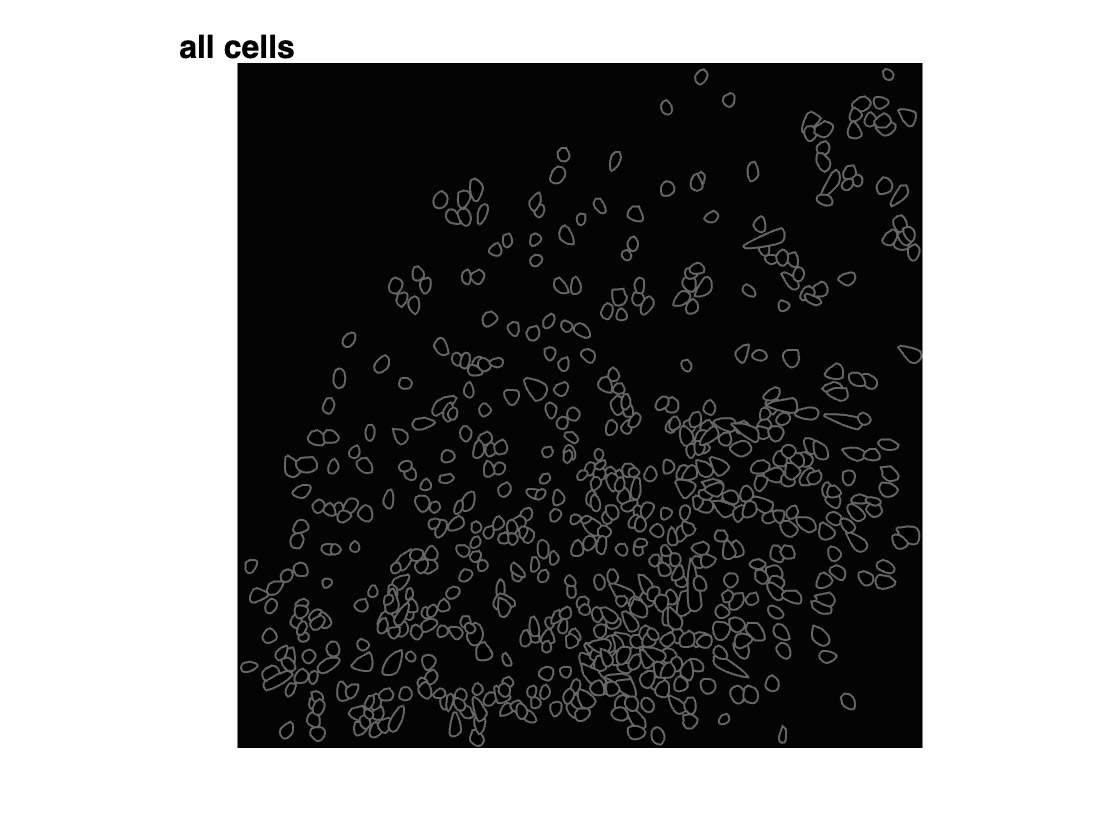

figure
image(backgroundimage)
colormap ("gray")
title ('all cells','Position', [0, 1.3, 0],'FontSize',16);

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell

    if colorcell(n)==1
        col='red';
    elseif colorcell(n)==2 
        col='green';
    elseif colorcell(n)==3 
        col='blue';
    elseif colorcell(n)==4 
        col='yellow';
    elseif colorcell(n)==5 
        col='magenta';
    elseif colorcell(n)==6 
        col='cyan';
    elseif colorcell(n)==7 
        col='white';
    elseif colorcell(n)==8 
        col='black';
    end

    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    % t = 1:numel(x);
    % ts = 1:0.05:numel(x);
    % xs = spline(t, x, ts);
    % ys = spline(t, y, ts);
    window_size=5;
    x_smoothed = movmean(x, window_size);
    y_smoothed = movmean(y, window_size);

    patch(x_smoothed, y_smoothed,'k','FaceAlpha', 1,'EdgeColor',[0.4, 0.4, 0.4],'LineWidth',1)
    % patch(x, y,col,'FaceAlpha', 0,'EdgeColor','w','LineWidth',1)
    % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    %plot(x, y, '.', 'MarkerSize', 4,"Color",col);
    axis off
    axis image
        

end

namegraph=strcat(PathSave ,['allcells' , '.png']);

exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')

figure
image(backgroundimage)
colormap ("gray")
title ('red cells','Position', [0, 1.3, 0],'FontSize',16);
        window_size=5;

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell
        x=cell2mat(outline_gcampx(n));
        y=cell2mat(outline_gcampy(n));
        sorted_indices = convhull(x, y); 
        x = x(sorted_indices);
        y = y(sorted_indices);
        x_smoothed = movmean(x, window_size);
        y_smoothed = movmean(y, window_size);
    if colorcell(n)==1
        col='red';
        patch(x_smoothed, y_smoothed,col,'FaceAlpha', 1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    else 
          patch(x_smoothed, y_smoothed,'k','FaceAlpha', 0.01,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    end
    axis off
    axis image
end

namegraph=strcat(PathSave ,['red_cells' , '.png']);

exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')


figure
image(backgroundimage)
colormap ("gray")
title ('green cells','Position', [0, 1.3, 0],'FontSize',16);
        window_size=5;

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    x_smoothed = movmean(x, window_size);
    y_smoothed = movmean(y, window_size);
    if colorcell(n)==2
        col='green';
        patch(x_smoothed, y_smoothed,col,'FaceAlpha', 1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    else
        patch(x_smoothed, y_smoothed,'k','FaceAlpha', 0.1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    end
    axis off
    axis image
end

namegraph=strcat(PathSave ,['green_cells' , '.png']);

exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')

figure
image(backgroundimage)
colormap ("gray")
title ('blue cells','Position', [0, 1.3, 0],'FontSize',16);
window_size=5;

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    x_smoothed = movmean(x, window_size);
    y_smoothed = movmean(y, window_size);
    if colorcell(n)==3
        col='blue';
        patch(x_smoothed, y_smoothed,col,'FaceAlpha', 1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    else
        patch(x_smoothed, y_smoothed,'k','FaceAlpha', 0.1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    end
    axis off
    axis image
end

namegraph=strcat(PathSave ,['blue_cells' , '.png']);

exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')

figure
image(backgroundimage)
colormap ("gray")
title ('yellow cells','Position', [0, 1.3, 0],'FontSize',16);
window_size=5;

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    x_smoothed = movmean(x, window_size);
    y_smoothed = movmean(y, window_size);
    if colorcell(n)==4
        col='yellow';
        patch(x_smoothed, y_smoothed,col,'FaceAlpha', 1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    else
        patch(x_smoothed, y_smoothed,'k','FaceAlpha', 0.1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    end
    axis off
    axis image
end

namegraph=strcat(PathSave ,['yellow_cells' , '.png']);

exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')

figure
image(backgroundimage)
colormap ("gray")
title ('magenta cells','Position', [0, 1.3, 0],'FontSize',16);
window_size=5;

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    x_smoothed = movmean(x, window_size);
    y_smoothed = movmean(y, window_size);
    if colorcell(n)==5
        col='magenta';
        patch(x_smoothed, y_smoothed,col,'FaceAlpha', 1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    else
        patch(x_smoothed, y_smoothed,'k','FaceAlpha', 0.1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    end
    axis off
    axis image
end

namegraph=strcat(PathSave ,['magenta_cells' , '.png']);

exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')

figure
image(backgroundimage)
colormap ("gray")
title ('cyan cells','Position', [0, 1.3, 0],'FontSize',16);
window_size=5;

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell
    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    x_smoothed = movmean(x, window_size);
    y_smoothed = movmean(y, window_size);
    if colorcell(n)==6
        col='cyan';
        patch(x_smoothed, y_smoothed,col,'FaceAlpha', 1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
    else
        patch(x_smoothed, y_smoothed,'k','FaceAlpha', 0.01,'EdgeColor',[0.1, 0.1, 0.1],'LineWidth',1)
    end
    axis off
    axis image
end

namegraph=strcat(PathSave ,['cyan_cells' , '.png']);

exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')

%plot assemblies
% backgroundimage=ones(512,512)*5;
for num=1:nbassemblies

    % fig = figure('visible','off');
    figure
    colormap ("gray")
    % imshow(backgroundimage);
    image(backgroundimage)
    % title (['assembly ' num2str(num) ':' , num2str(numel(cell2mat(assembly(num)))) , ' cells'],'Position', [0, 1.3, 0],'FontSize',16);
    %hold on

    %for n=transpose(cell2mat(assembly(num)))
    for n=1:NCell
        x=cell2mat(outline_gcampx(n));
        y=cell2mat(outline_gcampy(n));
        sorted_indices = convhull(x, y); 
        x = x(sorted_indices);
        y = y(sorted_indices);
        patch(x, y,'k','FaceAlpha', 0.1,'EdgeColor',[0.1, 0.1, 0.1],'LineWidth',0.1)
    end
    for n=cell2mat(assembly(num))
        if colorcell(n)==1
            col='red';
        elseif colorcell(n)==2 
            col='green';
        elseif colorcell(n)==3 
            col='blue';
        elseif colorcell(n)==4 
            col='yellow';
        elseif colorcell(n)==5 
            col='magenta';
        elseif colorcell(n)==6 
            col='cyan';
        elseif colorcell(n)==7 
            col='white';
        elseif colorcell(n)==8 
            col='black';
        end
        x=cell2mat(outline_gcampx(n));
        y=cell2mat(outline_gcampy(n));
        sorted_indices = convhull(x, y); 
        x = x(sorted_indices);
        y = y(sorted_indices);
        x = movmean(x, window_size);
        y = movmean(y, window_size);
        patch(x, y,col,'FaceAlpha', 1,'EdgeColor',[0.2, 0.2, 0.2],'LineWidth',1)
        % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
        % plot(x, y, '.', 'MarkerSize', 4,"Color",col);
        axis off
        axis image
        %hold off

    end
% Set the figure properties

% set(fig, 'Units', 'pixels');
% set(fig, 'PaperSize', [512 512]); 
% set(fig, 'Position', [0 0 512 512]); 
% set(fig, 'PaperPositionMode', 'auto');
% set(fig, 'Color', 'black');

namegraph=strcat(PathSave,['assembly', num2str(num) , '.png']);
exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')
% print(fig, namegraph, '-dpng', '-r0', '-noui');
end

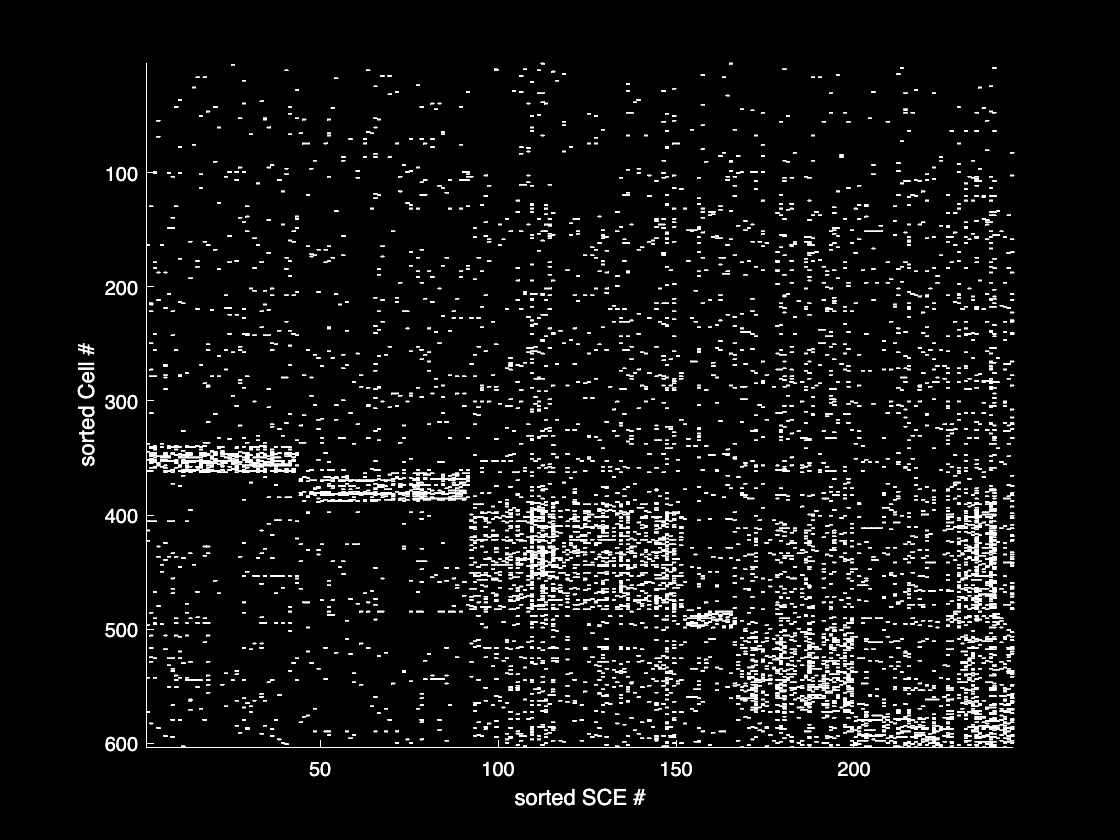

%new raster 
assembly=assemblyortho;

colors = [
    1 0 0;     % Red 
    0 1 0;     % Green
    0 0 1;     % Blue
    1 1 0;     % Yellow
    1 0 1;     % Magenta
    0 1 1;     % Cyan
    0.5 0 0;   % Maroon
    0 0.5 0;   % Olive
    0 0 0.5;   % Navy
    0.5 0.5 0; % Olive Green
    0.5 0 0.5; % Purple
    0 0.5 0.5; % Teal
    0.75 0 0;  % Dark Red
    0 0.75 0;  % Lime Green
    0 0 0.75;  % Dark Blue
    0.75 0.75 0; % Dark Yellow
    0.75 0 0.75; % Dark Magenta
    0 0.75 0.75; % Dark Cyan
];
Cl_order = [ Cl1  Cl2 Cl3 Cl4];
Cl_order = [Cl0 Cl1 Cl2 Cl3 Cl4];
% Race_ordered=Race(x1,Cl_order);

% fig = figure('visible','off');
fig=figure;
set(fig, 'Color', 'k'); % Set the figure background color to black

ax = axes('Parent', fig);
set(ax, 'Color', 'k'); % Set the axis background color to black
colors(NCl+1,:)=1;

cell_id=(NCl+1)*ones(1,NCell);

for n=1:NCl
    cell_id(1,cell2mat(assembly(n))) = n;
end
cell_id=cell_id(x1);

hold on
for n = 1:NCell
    for y=1:size(Race_ordered,2)
        if Race_ordered(n,y)>0
            rectangle('Position',[y,n, 1,1],'FaceColor','w','EdgeColor','w','LineWidth',0.1)
            
        end
    end
end

axis ij
axis tight
set(ax, 'XColor', 'w');
set(ax, 'YColor', 'w');
set(ax, 'Color', 'k');
xlabel('sorted SCE #')     %was RACE
ylabel('sorted Cell #')
% drawnow
hold off

namegraph=strcat(PathSave,'rasterashortwhite.png');
% exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')